clear all; clc; close all;
addpath('D:\GD\Sintesis de redes activas\sintesis_redes_activas\Tp4\Matlab_Files')
%--------------------------------------------------------------------------

## Parametros:

Fbp = [800 1250]; % Puntos en frecuencia de la banda de paso entre 800 y 1250 [Hz]
Fbr = [200 5000]; % Puntos en frecuencia de la banda de rechazo 0-200 [Hz] y 5000-inf [Hz]
Wbp = 2*pi*Fbp;   % Puntos de omega [rad/s]
Wbr = 2*pi*Fbr;   % Puntos en omega [rad/s]
Abp = 0.25;       % Atenuacion en la banda de paso [dB]
Abr = 30;         % Atenuacion en la banda de rechazo [dB]

## TF:

[n , Wp] = cheb1ord(Wbp,Wbr,Abp,Abr,"s");  % Determinacion del orden y la frecuencia de corte de un filtro de chebyshev tipo 1
[num , den] = cheby1(n,Abp,Wp,"s");        % Determinacion del numerador y denominador de la funcion de transferencia del filtro
TF_filtro = tf(num,den)                    % Creacion de la TF del filtro

TF_filtro =
 
                      1.642e07 s^2
  -----------------------------------------------------
  s^4 + 5080 s^3 + 9.586e07 s^2 + 2.006e11 s + 1.559e15
 
Continuous-time transfer function.




% Descomposicion en bicuadraticas (debemos descomponer en una funcion para
% filtro pasa-alto y otra para el filtro pasa-bajo):
[Msos , Gg] = tf2sos(num,den);             % Descompone en bicuadraticas
% Msos: matriz de coeficientes de la bicuadraticas ; Gg: ganancia global del filtro
TFpb = tf(Gg*Msos(1,1:3) , Msos(1,4:6))  % Funcion de transferencia del filtro pasa-bajo

TFpb =
 
         1.642e07
  -----------------------
  s^2 + 3184 s + 6.632e07
 
Continuous-time transfer function.



% 2*Gg*Msos(1,1:3): coeficiente del numerador escalados por la ganancia global, Msos(1,4:6): coeficiente del denominador
TFpa = tf(Msos(2,1:3) , Msos(2,4:6))     % Funcion de transferencia del filtro pasa-alto

TFpa =
 
           s^2
  ----------------------
  s^2 + 1896 s + 2.35e07
 
Continuous-time transfer function.



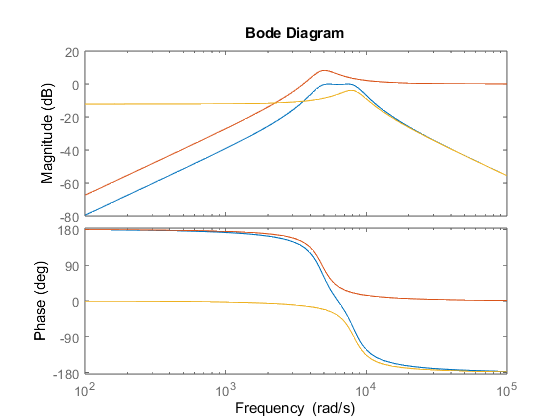

% 1/2*Msos(2,1:3): Coeficientes del numerador escalados por la ganancia global, Msos(2,4:6): Coeficientes del denominador

figure                    % Diagramas de bode juntos
hold on;
bode(TF_filtro);
bode(TFpa);
bode(TFpb);
hold off;

## Filtro pasa bajo:

[num_pb,den_pb] = tfdata(TFpb);                % Obtencion numerador y denominador de la TFpb
num_pb = cell2mat(num_pb);
num_pb = num_pb(3);
den_pb = cell2mat(den_pb);
[Kpb,Wpb,Qpb] = obt_coef(num_pb,den_pb);       % Obtencion de K, W y Q

% Tomamos R1 = R2 = 10000
syms C1pb C2pb;
R1pb = 10000;                                                 % Suponemos R1 para el FPB
R2pb = 10000;                                                 % Suponemos R2 para el FPB
eq1 = 1/(sqrt(C1pb*C2pb*R1pb*R2pb)) == Wpb;                   % Describimos la EC1
eq2 = sqrt(C1pb/C2pb)*(sqrt(R1pb*R2pb)/(R1pb+R2pb)) == Qpb;   % Describimos la EC2
solu1 = solve([eq1,eq2],[C1pb,C2pb]);                         % Obtenemos las soluciones de las ECs

C1_pb = double(solu1.C1pb(2))                                % Valor de C1

C1_pb = 6.2806e-08

C2_pb = double(solu1.C2pb(2))                                % Valor de C2

C2_pb = 2.4008e-09


% El K lo hacemos con un divisor resistivo

## Filtro pasa alto:

[num_pa,den_pa] = tfdata(TFpa);
num_pa = cell2mat(num_pa);
num_pa = num_pa(1);
den_pa = cell2mat(den_pa);
[Kpa,Wpa,Qpa] = obt_coef2(num_pa,den_pa);

%
%syms C1pa C2pa;
%R1pa = 6000;
%R2pa = 5000;
syms R1pa R2pa;
C1pa = 0.0000001;
C2pa = 0.0000001;
eq3 = 1/(sqrt(C1pa*C2pa*R1pa*R2pa)) == Wpa

$$eq3 = \frac{1}{\sqrt{\frac{\mathrm{R1pa}\,\mathrm{R2pa}}{100000000000000}}}=\frac{1332522734972479}{274877906944}$$

eq4 = 1/((sqrt(R1pa/R2pa)*((C1pa+C2pa)/sqrt(C1pa*C2pa)))+((1-Kpa)*sqrt((R2pa*C2pa)/(R1pa*C1pa)))) == Qpa

$$eq4 = \frac{1}{2\,\sqrt{\frac{\mathrm{R1pa}}{\mathrm{R2pa}}}}=\frac{1439671897139689}{562949953421312}$$

solu2 = solve([eq3,eq4],[R1pa,R2pa]);

R1_pa = double(solu2.R1pa(2))

R1_pa = 403.3123

R2_pa = double(solu2.R2pa(2))

R2_pa = 1.0551e+04